# 1.壁滞留的计算

## 1.1 粒子平衡法

粒子平衡方法是分析托卡马克中燃料粒子滞留的重要方法。EAST 托卡马克装置中基本的粒子平衡过程如下：

                                
$$Q_{retention} = Q_{puff} - Q_{pump} - Q_{vessel} - Q_{plasma}$$


$Q_{retention}$是总的D滞留量；$Q_{puff}$是总的加料量；$Q_{vessel}$是总的泵抽气量；$Q_{vessel}$是真空室内总的中性气体量；$Q_{plasma}$是等离子体中D的总量。

在 EAST 中，加料方式主要有普通充气，低杂波充气、离子回旋充气、超声分子束充气（SMBI）和中性束注入带来的加料(NBI)。其中，普通充气，低杂波充气、离子回旋充气、超声分子束 充气（SMBI）的加料充气量可以通过$\Delta P_{tank} \times V_{tank}$来计算，其中$\Delta P_{tank}$是充气罐气压的变化值，而$V_{tank}$是充气罐的体积；

$Q_{pump}$是被抽气系统抽出的气体粒子数, 它可以通过抽速与泵口气压乘积的积分进行计算$\int P_{pump} \times S dt$，$P_{pump}$代表抽气系统泵口的气压，S是抽气系统的抽速；

真空室中性粒子$Q_{vessel}$可以忽略，因为一般真空室的气压在放电过程中很低，变化更低，；

$Q_{plasma}$也可以忽略，因为在稳定放电的情况下，等离子体平均密度的变化很小，但是在下面的算法中计算了。

## 1.2 算法结构

加料部分：LWH部分，GAS PUFF 充气部分， ICRF充气部分， 偏滤器充气部分，SMBI部分（SMBI2+SMBI3），NBI注入部分；

抽气部分：低杂波两台低温泵抽气，所有分子泵（主抽4台+低杂波两台+离子回旋+壁处理1台），中平面5台低温泵，上偏滤器抽气（上内冷泵+上外冷泵），下偏滤器（下内冷泵+下外冷3台）

等离子体中D总量： $Q_{plasma}$

# 2.壁滞留算法

## 2.1 计算D气比例

clear ;
tic
% shot=95118;
shot=105458;
res_size = 10 ; % set resample size,暂时先不要改这个值

filepath='D:\li\zhipu\';
% zhipu=textread([filepath num2str(shot),'.txt'],'','headerlines',1);
file_name = [filepath, int2str(shot), '.txt'];
fileID = fopen(file_name);
zhipu = cell2mat(textscan(fileID,'%f %f %f %f %f %f %f %f %f %f %f %f', 'HeaderLines', 1)); % 有时候10列，有时候12列,统一读12列
[~,inx_time_begin] = min(abs(zhipu(:,1)-59)); %放电开始时刻的下标，最接近59的下标
[~,inx_time_end] = min(abs(zhipu(:,1)-300)); %放电结束时刻的下标，最接近300的下标
zhipu_sp = zhipu(inx_time_begin:inx_time_end,:); %从放电时间开始到结束的质谱数据
DH = (zhipu_sp(:, 4) .* 2 + zhipu_sp(:, 3)) ./ ((zhipu_sp(:, 2) + zhipu_sp(:, 3) + zhipu_sp(:, 4)) .* 2);
timeDH = zhipu_sp(:,1)-60;
P = polyfit(timeDH,DH,5); % 多项式未正确设置条件，将7修改成5

% Remote connect
mdsconnect('mds.ipp.ac.cn');
mdsopen('east', shot);%有时用east_1

% X-axis: time
time = mdsvalue('dim_of(\G107)');
time=time(1:res_size:end);
time1 = mdsvalue('dim_of(\ipm)');
time1=time1(1:res_size:end);

length_time=length(time);
length_time1=length(time1);
time_puffing=mdsvalue('dim_of(\jhg1)');
length_timepuffing=length(time_puffing);
PH=polyval(P,time); % D气比例；


## 2.2 设置罐体参数

% V_vessel = 110;
Pam2P = 2.41e20;

if shot>88344
    V_SMBI=2.0431e-4; 
else
    V_SMBI=3984.31.*(1e-6); %SMBI3充气罐子体积m-3
end
%2021对稳压罐进行重组，取消KHG1，JHG6,JHG3仅用于充Ar
%用于加料的罐子
V_JHG1 = 3.118e-4;%PUFF系统充气罐体积m-3
V_DHG1=2.919E-4;%D窗口E低杂波天线充气罐体积m-3 
V_JHG2 = 2.91e-4;%J窗口水平充气，位于偏滤器充气罐体积m-3
V_JHG4 = 2.99e-4;% N窗口北ICRF天线加料充气罐体积m-3
V_JHG5 = 2.997e-4; % N窗口南ICRF天线加料充气罐体积m-3
%V_KHG1=2.919E-4;%K窗口N低杂波天线充气罐体积m-3
%V_JHG6 = 2.949e-4;% J窗口南ICRF天线加料充气罐体积m-3

%用于偏滤器杂质气体充气
V_OUG1 = 1.4687e-3;% J窗口偏滤器充气罐体积m-3
V_ODG1 = 1.4601e-3;% J窗口偏滤器充气罐体积m-3
V_CDG1 = 6.792e-3;% J窗口偏滤器充气罐体积m-3
V_HDG1 = 6.75e-3;% J窗口偏滤器充气罐体积m-3

%规管系数
KH=2.9;



g107 = mdsvalue('\G107');
g105 = mdsvalue('\G105');
g109 = mdsvalue('\G109');
g106 = mdsvalue('\G106');

%缩短数据长度
g107=g107(1:res_size:end);
g105=g105(1:res_size:end);
g109=g109(1:res_size:end);
g106=g106(1:res_size:end);


G107 = 10.^(1.667*g107-9.333).*KH;
G105 = 10.^(1.667*g105-9.333).*KH;
G109 = 10.^(1.667*g109-9.333).*KH;
G106 = 10.^(1.667*g106-9.333).*KH;





VJHpev3=mdsvalue('\VJHpev3');
index=find(VJHpev3>0.3,1,'last'); % 找到最后一个下标
VJHpev3=VJHpev3(1:res_size:end);
%time_VJHpev3=mdsvalue('dim_of(\VJHpev3)'); % 没用到的值
% index=find(VJHpev3>0.3,1,'last'); % 找到最后一个下标
%-------------------------
jhg1=mdsvalue('\jhg1');
jhg2=mdsvalue('\jhg2');
dhg1=mdsvalue('\Dhg1');
jhg4=mdsvalue('\jhg4');
jhg5=mdsvalue('\jhg5');

%缩短数据长度
jhg1 = jhg1(1:res_size:end);
jhg2 = jhg2(1:res_size:end);
dhg1 = dhg1(1:res_size:end);
jhg4 = jhg4(1:res_size:end);
jhg5 = jhg5(1:res_size:end);


JHG1 = (jhg1-1)*2.5e4; % JHG1为充气信号，单位Pa
JHG2 = (jhg2-1)*2.5e4; % 
DHG1 = (dhg1-1)*2.5e4; %D窗口低杂波天线充气
JHG4 = (jhg4-1)*2.5e4; % B窗口北ICRF天线加料
JHG5 = (jhg5-1)*2.5e4; % J窗口南ICRF天线加料



%偏滤器加料
oug1=mdsvalue('\OUG1');
odg1=mdsvalue('\ODG1');
cdg1=mdsvalue('\CDG1');
hdg1=mdsvalue('\HDG1');

%缩短数据长度
oug1=oug1(1:res_size:end);
odg1=odg1(1:res_size:end);
cdg1=cdg1(1:res_size:end);
hdg1=hdg1(1:res_size:end);

OUG1 = (oug1-1)*2.5e4; % J窗口偏滤器
ODG1 = (odg1-1)*2.5e4; % J窗口偏滤器
CDG1 = (cdg1-1)*2.5e4; % J窗口偏滤器
HDG1 = (hdg1-1)*2.5e4; % J窗口偏滤器



%缩短数据长度

%NBI 注入电流信号
% 这里没有重采样，看看是不是需要重新处理一下
NBI1LHI=0.8.*(mdsvalue('\NBI1LHI'));
NBI1RHI=0.8.*(mdsvalue('\NBI1RHI'));
NBI2LHI=0.8.*(mdsvalue('\NBI2LHI'));
NBI2RHI=0.8.*(mdsvalue('\NBI2RHI'));
time_NBI=mdsvalue('dim_of(\NBI2RHI)');



% ipm = mdsvalue('\ipm');% 应该也没用上


background = mean(G107(1:1000/res_size));
G107 = G107-background;


## 2.3 充气部分

### 2.3.1 LHW部分

background_DHG1 = mean(DHG1(1:50000/res_size));
puff_DHG = zeros(length_time,1);
if max(dhg1)-min(dhg1) >= 0.3
    puff_DHG= V_DHG1*(background_DHG1-DHG1);
end
% if max(dhg1)-min(dhg1)<0.3
%     DHG1=zeros(length_time,1);
%     puff_DHG=V_DHG1.*DHG1;
% else
%     for j=1:length_time
%         puff_DHG(j,1)= V_DHG1*(background_DHG1-DHG1(j));
%     end
% end
puff_LHW=puff_DHG;
puff_LHW=smooth(puff_LHW,10000/res_size,'sgolay');
% [~,M_LHW] = max(puff_LHW);
% puff_LHWlong(1:M_LHW)=puff_LHW(1:1:M_LHW);
% puff_LHWlong((M_LHW+1):length_time)=ones(length_time-M_LHW,1) * puff_LHW(M_LHW);
[M_LHW,N_LHW]=find(puff_LHW==max(puff_LHW));
puff_LHWlong = zeros(size(time));
M_LHW=M_LHW(1);
if length(M_LHW)>10
    puff_LHWlong=puff_LHW;  % 啥意思没看懂??????
else
    puff_LHWlong(1:M_LHW)=puff_LHW(1:M_LHW);
    puff_LHWlong((M_LHW+1):end)=puff_LHW(M_LHW); % 改一下
end
puff_LHWlong=smooth(puff_LHWlong,1000/res_size,'sgolay');


### 2.3.2 GAS PUFF充气部分 JHG1+JHG2

background_JHG1 = mean(JHG1(1:5000/res_size));
JHG1=smooth(JHG1,1000/res_size,'sgolay');

puff_JHG1= V_JHG1*(background_JHG1-JHG1);  

background_JHG2 = mean(JHG2(1:5000/res_size));
JHG2=smooth(JHG2,1000/res_size,'sgolay');

puff_JHG2= V_JHG2*(background_JHG2-JHG2);  

puff_GAS=puff_JHG1+puff_JHG2;
puff_GAS=smooth(puff_GAS,10000/res_size,'sgolay');%提前平滑处理，避免放电结束后出现抖动带来大误差
M_GAS=floor(index ./ 10);
puff_GASlong = zeros(size(time));
puff_GASlong(1:M_GAS)=puff_GAS(1:M_GAS);
puff_GASlong((M_GAS+1):end)=puff_GASlong(M_GAS);

### 2.3.3 ICRF充气部分

background_JHG4 = mean(JHG4(1:5000/res_size));
background_JHG5 = mean(JHG5(1:5000/res_size));

puff_JHG4 = zeros(size(time));

if max(jhg4)-min(jhg4) >= 0.3
    puff_JHG4 = V_JHG4 * (background_JHG4-JHG4);
end
% puff_JHG4;

puff_JHG5 = zeros(size(time));

if max(jhg5)-min(jhg5) >= 0.3
    puff_JHG5 = V_JHG5 * (background_JHG5-JHG5);
end
% puff_JHG5;
puff_ICRF=puff_JHG4+puff_JHG5;
puff_ICRF=smooth(puff_ICRF,1000/res_size,'sgolay');

[M_ICRF,N_ICRF]=find(puff_ICRF==max(puff_ICRF));
puff_ICRFlong = zeros(size(time));
if length(M_ICRF)>10
    puff_ICRFlong=puff_ICRF;
else
    puff_ICRFlong(1:M_ICRF)=puff_ICRF(1:M_ICRF);
    puff_ICRFlong((M_ICRF+1):end) = puff_ICRF(M_ICRF);
end
puff_ICRFlong=smooth(puff_ICRFlong,1000/res_size,'sgolay');

### 2.3.4 偏滤器充气部分

%偏滤器充气部分
background_OUG1 = mean(OUG1(1:50000/res_size));
background_ODG1 = mean(ODG1(1:50000/res_size));
background_CDG1= mean(CDG1(1:50000/res_size));
background_HDG1= mean(HDG1(1:50000/res_size));

% puff_OUG1;
puff_OUG1 = zeros(size(time));

if max(oug1)-min(oug1) >= 0.3 
   puff_OUG1 = V_OUG1 * (background_OUG1 - OUG1);
end

% puff_CDG1;
puff_CDG1 = zeros(size(time));
if max(cdg1)-min(cdg1) >= 0.3
   puff_CDG1 = V_CDG1 * (background_CDG1-CDG1);
end

% puff_ODG1;
puff_ODG1 = zeros(size(time));
if max(odg1)-min(odg1) >= 0.3
    puff_ODG1= V_ODG1 * (background_ODG1-ODG1);
end

% puff_HDG1;
puff_HDG1 = zeros(size(time));
if max(hdg1)- min(hdg1) >= 0.3
   puff_HDG1= V_HDG1*(background_HDG1-HDG1);
end

puff_divertor = puff_OUG1+puff_CDG1 + puff_ODG1 + puff_HDG1;
puff_divertor = smooth(puff_divertor,1000/res_size,'sgolay');
[M_divertor,N_divertor] = find(puff_divertor == max(puff_divertor));
puff_divertorlong = zeros(size(time));
if length(M_divertor) > 10
    puff_divertorlong=puff_divertor;
else
    puff_divertorlong(1:M_divertor)=puff_divertor(1:M_divertor);
    puff_divertorlong((M_divertor+1):end) = puff_divertor(M_divertor);
end
puff_divertorlong = smooth(puff_divertorlong,100,'sgolay');

### 2.3.5 SMBI部分

mdsopen('east', shot);
%SMBI部分 SMBI2信号为PAS,SMBI3信号为PJS
%SMBI2加料
SMBI2=mdsvalue('\SMBI2');
time_SMBI001=mdsvalue('dim_of(\SMBI2)');
%SMBI_zs=mean(SMBI2(1:70000));
MAXSMBI=max(SMBI2);
PJS203=(mdsvalue('\PJS203') .* (4*10^5));%data link and rectify
time_PJS203=mdsvalue('dim_of(\PJS203)');
background2 = mean(PJS203(6970:7000));%SMBI罐子初始压强，为什么要这么选？
SMBI2g= V_SMBI*(background2-PJS203); %罐子内气体摩尔量变化
%SMBI2g=SMBI2g(1:10:length_time,1);%数据太多，取原来的十分之一有问题，有啥问题？

% if V_SMBI==3984.31*(1e-6) %SMBI3充气罐子体积m-3,浮点数相等不能这么写
if 3984.31*(1e-6) - V_SMBI < 1e-6 %SMBI3充气罐子体积m-3
    SMBI2g=smooth(SMBI2g,5000,'sgolay');
else
    SMBI2g=smooth(SMBI2g,100,'sgolay');
end
SMBI2g(SMBI2g < 0) = 0;
% for i=1:10*length_time
%    if SMBI2g(i)<0
%         SMBI2g(i)=0;
%    end
% end
[M1,N1]=find(SMBI2g==max(SMBI2g));
if length(M1)>1
    M1=M1(end);
end
SMBIlong2g = zeros(length(SMBI2g),1);
SMBIlong2g(1:M1) = SMBI2g(1:M1);
SMBIlong2g(M1+1:end) = SMBIlong2g(M1);
% SMBIlong2g(1:1:M1,1)=SMBI2g(1:1:M1,1);
% SMBIlong2g((M1+1):1:end, 1) = ones(length(SMBI2g)-M1,1) * SMBIlong2g(M1,1);

if MAXSMBI<1.4
    SMBIlong2g(1:end)=0;
end
SMBI_zs2=mean(SMBI2(1:70000));
SMBI002=SMBI2-SMBI_zs2;
SMBIlong2=cumtrapz(time_SMBI001, SMBI002);
SMBIlong2=SMBIlong2(1:res_size:end);
SMBIlong2g=SMBIlong2g(1:res_size:end);
%SMBIlong2=SMBIlong2(1:length_time);

rate = 2 * Pam2P * SMBIlong2g ./ SMBIlong2; %有问题？？
rate(rate == Inf) = 0 ;
% for i=1:1:length(time)
%     rate(i,1)=2*Pam2P*SMBIlong2g(i,1)./SMBIlong2(i,1);
%     if SMBIlong2(i,1)==0
%         rate(i,1)=0;
%     end
% end
coeff=abs(mean(rate(11000:1:end)));
SMBIlong22=coeff*SMBIlong2;
SMBIlong22=SMBIlong2g; % 原来这行没有注释，那上面不是白算了吗

SMBI3 加料


%SMBI3加料
SMBI3=mdsvalue('\SMBI3');
time_SMBI002=mdsvalue('dim_of(\SMBI3)');
MAXSMBI3=max(SMBI3);
PAS103=(mdsvalue('\PAS103').*(4*10^5));%data link and rectify
time_PAS103=mdsvalue('dim_of(\PAS103)');
background3 = mean(PAS103(69300:70000));%SMBI罐子初始压强
SMBI3g= V_SMBI*(background3-(PAS103)); %罐子内气体摩尔量变化
%SMBI3g=SMBI3g(1:10:(10*length_time),1);%数据太多，取原来的十分之一

% if V_SMBI==3984.31*(1e-6) %SMBI3充气罐子体积m-3
if 3984.31*(1e-6) - V_SMBI < 1e-6 %SMBI3充气罐子体积m-3
    SMBI3g=smooth(SMBI3g,5000,'sgolay');
else
    SMBI3g=smooth(SMBI3g,100,'sgolay');
end
%SMBI=SMBI2+SMBI3;
%将SMBI3g为0的元素设置为0
SMBI3g(SMBI3g<0) = 0;
% for i=1:10*length_time
%    if SMBI3g(i)<0
%         SMBI3g(i)=0;
%    end
% end
%SMBI=smooth(SMBI,5000,'sgolay');
[M2,N2]=find(SMBI3g==max(SMBI3g));
SMBIlong3g  = zeros(size(PAS103));
SMBIlong3g(1:M2)=SMBI3g(1:M2);
SMBIlong3g((M2+1):end)=SMBIlong3g(M2,1);

if MAXSMBI3<1.4
    SMBIlong3g(1:end)=0;
end

SMBI_zs3=mean(SMBI3(1:70000));
SMBI003=SMBI3-SMBI_zs3;
SMBIlong3=cumtrapz(time_SMBI002,SMBI003);

SMBIlong3=SMBIlong3(1:res_size:end);
SMBIlong3g=SMBIlong3g(1:res_size:end);
%SMBIlong3=SMBIlong3(1:length_time);

rate = 2 * Pam2P * SMBIlong3g ./ SMBIlong3;
rate(rate==Inf) = 0 ;
% for i=1:1:length(time)
%     rate(i,1)=2*Pam2P*SMBIlong3g(i,1)./SMBIlong3(i,1);
%     if SMBIlong3(i,1)==0
%         rate(i,1)=0;
%     end
% end
coeff=abs(mean(rate(11000:1:end)));
SMBIlong33=coeff*SMBIlong3;
SMBIlong33=SMBIlong3g;
SMBIlong=2 * Pam2P * (SMBIlong33 + SMBIlong22);   %求和
% SMBIlong=SMBIlong(1:res_size:end);

### 2.3.6 NBI部分

%NBI 注入部分
background_NBI1LHI=mean(NBI1LHI(1:1500));
NBI1LHI=NBI1LHI-background_NBI1LHI;
background_NBI1RHI=mean(NBI1RHI(1:1500));
NBI1RHI=NBI1RHI-background_NBI1RHI;
background_NBI2RHI=mean(NBI2RHI(1:1500));
NBI2RHI=NBI2RHI-background_NBI2RHI;
background_NBI2LHI=mean(NBI2LHI(1:1500));
NBI2LHI=NBI2LHI-background_NBI2LHI;
NBI_add= NBI1LHI+NBI1RHI+NBI2LHI+NBI2RHI;
NBI_add= cumtrapz(time_NBI, NBI_add);
%NBI_add2=NBI_add(1:5:end);
NBI_add2=interp1(time_NBI,NBI_add,time1,'linear');
NBI_addlong = zeros(size(time));
NBI_addlong(1:length_time1)= NBI_add2;
NBI_addlong(length_time1+1:end)= NBI_add2(length_time1);



## 2.4 总抽气量

### 2.4.1 低杂波两台低温泵抽气

%低杂波两台低温泵抽气
pump_LHWlow = G107;
pump_LHWlow(pump_LHWlow <= 1.3e-3) = 1.3e-3;
pump_LHWlow = 1.32 * pump_LHWlow .^ (-0.2757)-0.3481;
% for i=1:length_time
%     if G107(i,1)>1.3*10^(-3)
%         pump_LHWlow(i,1)=(1.32*(G107(i,1)).^(-0.2757)-0.3481); %校准后的关系式（ax^b+c,abc 1.32 -0.2757 -0.3481)
%     else%vif G107(i,1)<1.3*10^(-3)&&G107(i,1)==1.3*10^(-3)
%         pump_LHWlow(i,1)=(1.32*(1.3*10^(-3)).^(-0.2757)-0.3481); 
%     end
% end

### 2.4.2 所有分子泵（主抽4台+低杂波两台+离子回旋+壁处理1台）

%所有分子泵（主抽4台+低杂波两台+离子回旋+壁处理1台）
pump_midallcry = G107;
pump_midallcry(pump_midallcry <= 7e-4) = 7e-4;
pump_midallcry = 11.56*(pump_midallcry).^(-0.1736)-9.375;
% for i=1:length_time
%     if G107(i,1)>7*10^(-4)
%         pump_midallcry(i,1)=(11.56*(G107(i,1)).^(-0.1736)-9.375); %校准后的关系式（ax^b+c,abc 11.56 -0.1736 9.375)
%     else%if G107(i,1)<7*10^(-4)&&G107(i,1)==7*10^(-4)
%         pump_midallcry(i,1)=(11.56*(7*10^(-4)).^(-0.1736)-9.375); 
%     end
% end

### 2.4.3 中平面5台低温泵抽气

%中平面5台低温泵抽气
pump_middw = G107;
pump_middw(pump_middw <= 7e-4) = 7e-4;
pump_middw = 5.667 * pump_middw .^ (-0.2915);
% for i=1:length_time
%     if G107(i,1)>7*10^(-4)
%         pump_middw(i,1)=(5.667*(G107(i,1)).^(-0.2915)); %校准后的关系式（ax^b,ab 5.667 -0.2915)
%     else %G107(i,1)<7*10^(-4)&&G107(i,1)==7*10^(-4)
%         pump_middw(i,1)=(5.667*(7*10^(-4)).^(-0.2915)); 
%     end
% end
pump_mid = (pump_LHWlow + pump_midallcry + pump_middw) .* G107;

### 2.4.4 上偏滤器抽气

%上偏滤器内冷泵抽气
pump_upin = G109;
pump_upin(pump_upin <= 6.2e-3) = 6.2e-3;
pump_upin = 0.829* pump_upin.^(-0.7144)+19.71;
% for i=1:length_time
%      if G109(i,1)>6.2*10^(-3)
%         pump_upin(i,1)=(0.829*(G109(i,1)).^(-0.7144)+19.71); %校准后的关系式（ax^b+c)
%      else %if G109(i,1)<6.2^(-3)&&G109(i,1)==6.2^(-3)
%         pump_upin(i,1)=(0.829*(6.2*10^(-3)).^(-0.7144)+19.71);
%          
%      end
% end
%上外冷泵抽气
pump_upout = G109;
pump_upout(pump_upout <= 5e-3) = 5e-3;
pump_upout = 0.8307 * pump_upout .^ (-0.4968) + 3.69;
% for i=1:length_time
%      if G109(i,1)>5*10^(-3)
%         pump_upout(i,1)=(0.8307*(G109(i,1)).^(-0.4968)+3.69); %校准后的关系式（ax^b+c,a=0.8307,b=-0.4968,c=3.69)
%      else %if G109(i,1)<5*10^(-3)&&G109(i,1)==5*10^(-3)
%         pump_upout(i,1)=(0.8307*(5*10^(-3)).^(-0.4968)+3.69);
%         
%      end
% end
pump_up = (pump_upin+pump_upout) .* G109;

### 2.4.5 下偏滤器抽气

%下偏滤器内冷泵抽气
pump_lowin = G106;
pump_lowin(pump_lowin <= 6.9e-3) = 6.9e-3;
pump_lowin = 2.062 * pump_lowin .^ (-0.49) + 21.26;
% for i=1:length_time
%     if G106(i,1)>6.9*10^(-3)
%         pump_lowin(i,1)=(2.062*(G106(i,1)).^(-0.49)+21.26);%(abc,2.062,-0.49,21.26)
%     else%if G106(i,1)<6.9*10^(-3)&&G106(i,1)==6.9*10^(-3)
%         pump_lowin(i,1)=(2.062*(6.9*10^(-3)).^(-0.49)+21.26);
%     end
% end
%下外冷泵3台抽气
pump_lowout = G106;
pump_lowout( pump_lowout <= 5.1e-3 ) = 5.1e-3;
pump_lowout = 0.2514 * pump_lowout .^ (-0.4809) + 2.462;
% for i=1:length_time
%     if G106(i,1)>5.1*10^(-3)
%         pump_lowout(i,1)=(0.2514*(G106(i,1)).^(-0.4809)+2.462);%(abc,2.062,-0.49,21.26)
%     else%if G106(i,1)<5.1*10^(-3)&&G106(i,1)==5.1*10^(-3)
%         pump_lowout(i,1)=(0.2514*(5.1*10^(-3)).^(-0.4809)+2.462);
%     end
% end
pump_low=(pump_lowout+pump_lowin) .* G106;  
pump = pump_mid + pump_up + pump_low;   
pump = cumtrapz(time, pump);

## 2.5  等离子体D总量

mdsopen('efit_east', shot);
c = mdsvalue('\volume');
b = mdsvalue('dim_of(\volume)');
V_plasma = spline(b,c,time);
V_plasma(time < b(end) & time > b(1)) = 0 ;
V_plasma(V_plasma < 0) = 0;

% for i = 1:length_time
%     if time(i)<max(b) && time(i)>min(b)
%         V_plasma(i) = spline(b, c, time(i));
%     else
%         V_plasma(i) = 0;
%     end
%     if V_plasma(i)<0
%        V_plasma(i)=0;
%     end
% end
% V_plasma = V_plasma';

mdsopen('pcs_east', shot);
B = mdsvalue('\dfsdev');
A = mdsvalue('dim_of(\dfsdev)');
% B = y';
% A=x';
%mdsclose;
Ne = spline(A,B,time);
Ne(time < A(end) & time > A(1)) = 0 ;
Ne(Ne < 0) = 0 ;
% for i = 1:length_time
%     if time(i)<max(A) && time(i)>min(A)
%         Ne(i) = spline(A, B, time(i));
%     else
%         Ne(i) = 0;
%     end
%    % if Ne(i) < 0
%    %     Ne(i) = 0;
%     %end
% end
% Ne = Ne';
P_plasma = 1e19 .* Ne .* V_plasma ./ 1e6; % 结果为0

# 3. 壁滞留计算


% PH = 0.5;
V=60;%真空室体积；
R=8.31;
QVV=2.*PH.*G107.*V./(300*R) *6.02*10^23;%真空室内的中性粒子数;
%QVV=QVV(1:length_time,:);
puff_all=puff_LHWlong+puff_GASlong+puff_ICRFlong+puff_divertorlong;
%puff_all=smooth(puff_all,100,'sgolay');

add_all=2*Pam2P*(puff_all)+SMBIlong+NBI_addlong.*6.25*10^(18);
%add_all=2*Pam2P*(puff_all);
add_all=smooth(add_all,500,'sgolay');

retention = add_all - 2 * Pam2P .* PH .*pump - QVV;
retention_wall = retention-P_plasma;
retention_wall = smooth(retention_wall,100,'sgolay');
[~,m] = max(retention_wall);
recover_wall = zeros(size(retention));
max_ret = max(retention);
recover_wall(m+1:end) = max_ret - retention(m+1:end);
% for i=1:1:length(retention_wall)
%     if i<m+1
%         recover_wall(i,1)=0;
%     else
%         recover_wall(i,1)=max(retention_wall)-retention_wall(i,1);
%     end
% end
recover_wall;
retention_ratio = retention_wall ./ add_all;

% writematrix([time,retention_ratio],'retention_ratio_ph.csv')

PUMP = 2 * Pam2P .* PH .* pump;
PP = max(PUMP);
mdsclose;

# 4. 绘图

figure 1

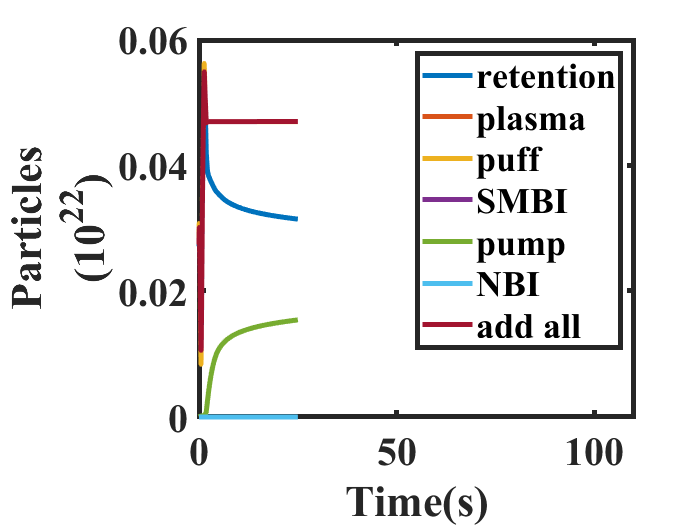

figure(1);
plot(time,retention_wall/1e22,time,P_plasma/1e22,time,2*Pam2P*puff_all/1e22,time,SMBIlong/1e22,time,2.*Pam2P.*PH.*pump/1e22,time,NBI_addlong.*6.25*10^(18)/1e22,time,add_all/1e22,'linewidth',3)
xlabel(('Time(s)'));
xlim([0 110]);
ylabel({'Particles','(10^{22})'});
legend('retention','plasma','puff','SMBI','pump','NBI','add all');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'linewidth',3);

figure 2

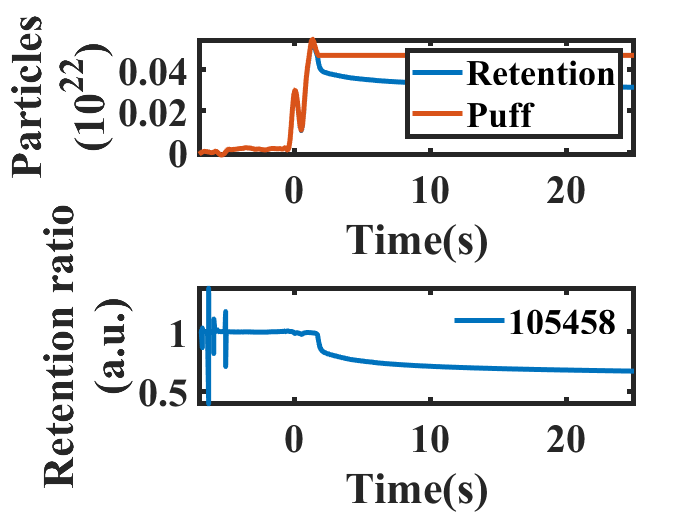

figure(2);
subplot(2,1,1)
plot(time,retention_wall/1e22,time,add_all/1e22,'linewidth',3)
xlabel(('Time(s)'));
ylabel({'Particles','(10^{22})'});
legend('Retention','Puff');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'linewidth',3); 
subplot(2,1,2)
plot(time,retention_ratio,'linewidth',3)
xlabel(('Time(s)'));
ylabel({'Retention ratio','(a.u.)'});
legend(num2str(shot));
legend('boxoff');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'linewidth',3);

figure 3

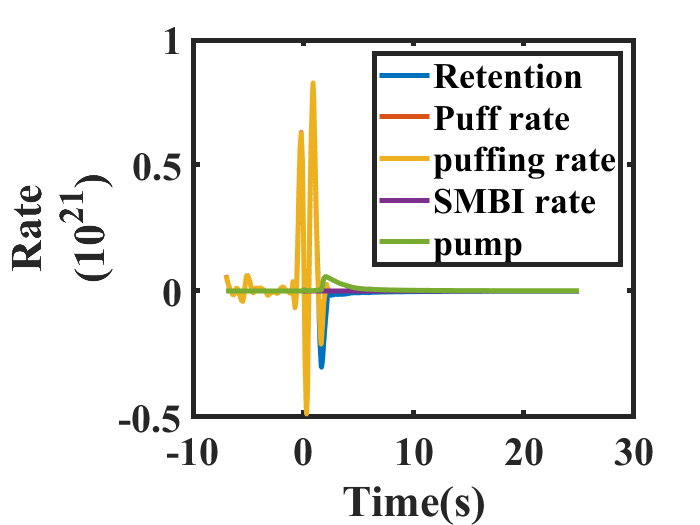

figure(3)
retention_rate=diff(retention_wall).*1000;
retention_rate=smooth(retention_rate,1000,'sgolay');
puff_rate=diff(add_all).*1000;
puff_rate=smooth(puff_rate,1000,'sgolay');
puffing_rate=diff(puff_all).*1000;
puffing_rate=2*Pam2P*smooth(puffing_rate,1000,'sgolay');
SMBI_rate=diff(SMBIlong).*1000;
SMBI_rate=smooth(SMBI_rate,1000,'sgolay');
pump_rate=diff(PUMP).*1000;
plot(time(1:end-1),retention_rate/1e21,time(1:end-1),puff_rate/1e21,time(1:end-1),puffing_rate/1e21,time(1:end-1),SMBI_rate/1e21,time(1:end-1),pump_rate/1e21,'linewidth',3)
xlabel(('Time(s)'));
ylabel({'Rate','(10^{21})'});
legend('Retention','Puff rate','puffing rate','SMBI rate','pump');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'linewidth',3);

figure 4

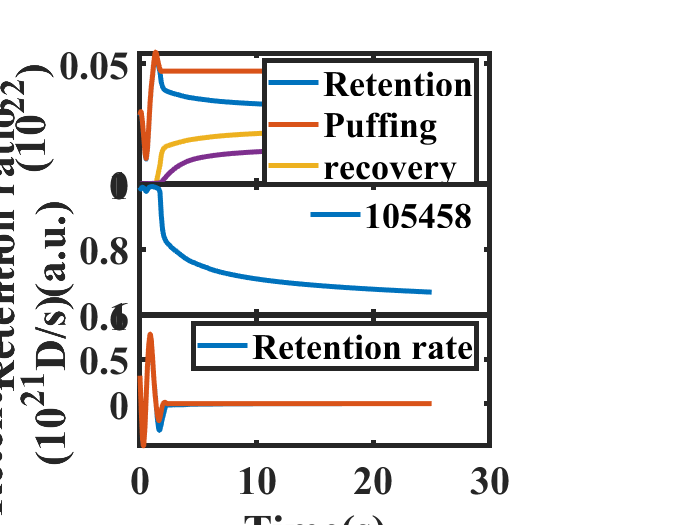

figure(4)
subplot(3,1,1)
set(gca,'position',[0.2 0.65 0.5 0.25]);
plot(time,retention_wall/1e22,time,add_all/1e22,time,recover_wall/1e22,time,PUMP/1e22,'linewidth',3)
xlim([0 30]);
xlabel(('Time(s)'));
ylabel({'Particles','(10^{22})'});
legend('Retention','Puffing','recovery','pumping');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'XTickLabel','','linewidth',3);
set(gca,'linewidth',3);
subplot(3,1,2)
set(gca,'position',[0.2 0.4 0.5 0.25]);
plot(time,retention_ratio,'linewidth',3)
xlim([0 30]);% 时间都要从0时刻开始吗？
ylabel({'Retention ratio','(a.u.)'});
legend(num2str(shot));
legend('boxoff');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'XTickLabel','','linewidth',3);
set(gca,'linewidth',3);
subplot(3,1,3)
set(gca,'position',[0.2 0.15 0.5 0.25]);
plot(time(1:end-1),retention_rate/1e21,time(1:end-1),puff_rate/1e21,'linewidth',3)
xlim([0 30]);
xlabel(('Time(s)'));
ylabel({'Retention rate','(10^{21}D/s)'});
legend('Retention rate');
set(get(gca,'xlabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(get(gca,'ylabel'),'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'Fontname','Times New Roman','FontSize',24,'Fontweight','bold');
set(gca,'linewidth',3);

toc

历时 11.889357 秒。
